onsets = saccade.start_timestamp(:);
offsets = saccade.end_timestamp(:);

saccade_dur_ms = round((offsets-onsets)*1000);


max_saccade_dur = max(saccade_dur_ms);
min_saccade_dur = min(saccade_dur_ms);



figure;bar(sort(saccade_dur_ms));xlabel('n of saccades');ylabel('saccade duration (msec)')

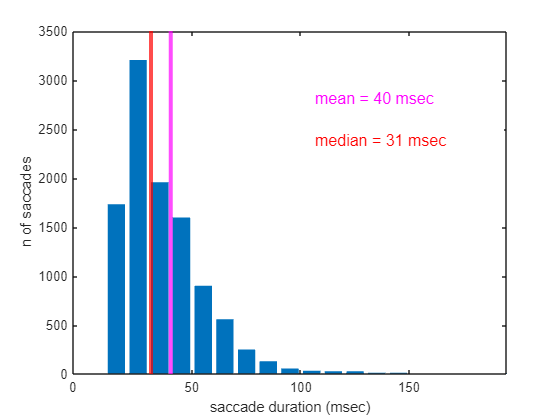


edges = [0:10:2000];
saccade_dur_hist = histc(saccade_dur_ms,edges);
figure;bar(saccade_dur_hist);
xticks([0 5.5 10.5 15.5 20.5])
xticklabels({'0','50','100','150','200'})
xlabel('saccade duration (msec)');ylabel('n of saccades');
xlim([0 20])
median_saccade_dur = median(saccade_dur_ms);
xline((median_saccade_dur/10)+0.5,'r','LineWidth',3)
mean_saccade_dur = mean(saccade_dur_ms);
xline((mean_saccade_dur/10)+0.5,'m','LineWidth',3)

annotation('textbox',...
    [0.55 0.65 0.35 0.15],...
    'String',{sprintf('mean = %d msec',round(mean_saccade_dur))},...
    'FontSize',12,...
    'FontName','Arial',...
    'LineStyle','--',...
    'EdgeColor',[1 1 1],...
    'LineWidth',2,...
    'BackgroundColor',[1 1 1],...
    'Color','m');

annotation('textbox',...
    [0.55 0.55 0.35 0.15],...
    'String',{sprintf('median = %d msec',round(median_saccade_dur))},...
    'FontSize',12,...
    'FontName','Arial',...
    'LineStyle','--',...
    'EdgeColor',[1 1 1],...
    'LineWidth',2,...
    'BackgroundColor',[1 1 1],...
    'Color','r');

%find the outliers

long_sacc = find(saccade_dur_ms>500);numel(long_sacc)
% some 0.7% of saccades are longer than 200 ms and 0.3% are longer than 500 ms.

%saccade velocity modulation, as defined by Marco. The pre-saccade
%modulated neurons might be involved in planning. maybe i should look at
%the cross-correlograms of before vs. after to see if they are correlated
%more than the chance level. also, saccades and 'boundaries', as defined by
% Ueli&Jie might be somehow related (units tuned to both are in the
% temporal lobe, they both relate to discontinuity). 



for i = 1:size(neural,1)
    
     spike_timestamps = cell2mat(neural.Timestamps(i))*1000; %converting unix time to msec
    count=1;
    for ii = 1:size(saccade,1)
        
        if strcmp(cell2mat(neural.patient_id(i)),cell2mat(saccade.patient_id(ii)))==1
            saccade_onset = saccade.start_timestamp(ii)*1000;
            saccade_offset = saccade.end_timestamp(ii)*1000;
            
            onset_locked_spiking_cell{count} = spike_timestamps(find(spike_timestamps>(saccade_onset - 100) & spike_timestamps<(saccade_onset + 100))) - saccade_onset;
            offset_locked_spiking_cell{count} = spike_timestamps(find(spike_timestamps>(saccade_offset - 100) & spike_timestamps<(saccade_offset + 100))) - saccade_offset;
            count=count+1;
        end
    end
    
  onset_locked_firing{i} = onset_locked_spiking_cell'; clear onset_locked_spiking_cell;
  offset_locked_firing{i} = offset_locked_spiking_cell'; clear offset_locked_spiking_cell;
i
end





neural = addvars(neural,onset_locked_firing');
neural = addvars(neural,offset_locked_firing');


neural.Properties.VariableNames(87) = "saccade_onset_locked_firing";
neural.Properties.VariableNames(88) = "saccade_offset_locked_firing";

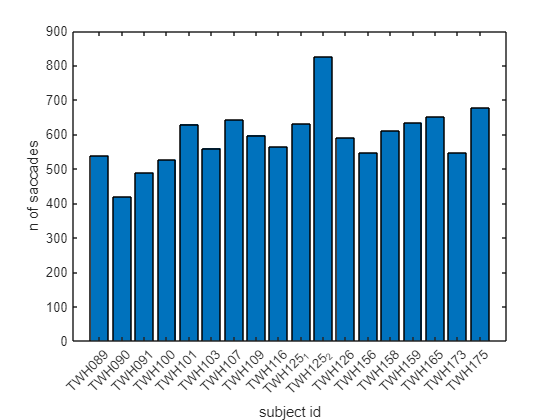

patient_id = summary.patient_id;
n_of_sacc = summary.total_number_of_saccades;

figure;bar(n_of_sacc);xticks([1:numel(patient_id)]); xticklabels(patient_id);ylabel('n of saccades');xlabel('subject id')

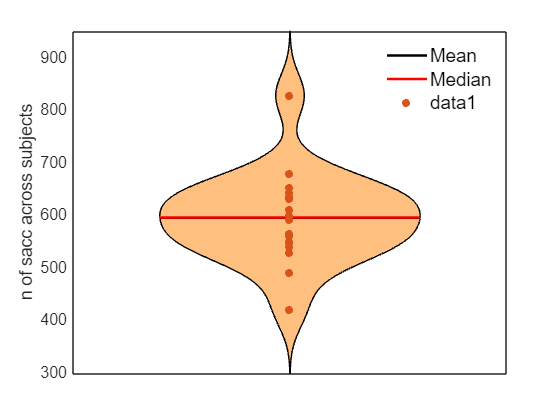

mean_n_sacc = mean(n_of_sacc); sem_n_sacc = std(n_of_sacc)/sqrt(numel(n_of_sacc));

figure;violin(n_of_sacc);hold on; scatter(ones(1,numel(n_of_sacc)),n_of_sacc,'o','filled'); xticks([]); ylabel('n of sacc across subjects');

%see if the n of saccades varies with trial#
for i = 1:numel(patient_id)
     count=1;
    for ii = 1:size(saccade,1)
        curr_id = saccade.patient_id(ii);
        if strcmp(patient_id{i}, curr_id{1})==1
            patient_unique_saccade_trl_list{i}(count) = saccade.scene_id(ii); count = count+1;
        end
    end
end

edges = [0:41];

for i = 1:numel(patient_unique_saccade_trl_list)
    a = histc(patient_unique_saccade_trl_list{i}, edges);
    sacc_trl_hist{i} = a(2:41);
end

sacc_trl_hist_mat = cell2mat(sacc_trl_hist);
n_of_trials = 40;

start_ind=1; end_ind = n_of_trials;

for i = 1:numel(patient_id)
    subj_id(start_ind:end_ind) = i; 
    trial_ind(start_ind:end_ind) = [1:40];
    start_ind = start_ind + n_of_trials; end_ind = end_ind + n_of_trials;
end

% 
tbl = table(subj_id', trial_ind', sacc_trl_hist_mat','VariableNames',{'subj_id','trial_ind','sacc_trl'});

lme = fitlme(tbl,'sacc_trl ~ 1 + trial_ind + (1|subj_id)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             720
    Fixed effects coefficients           2
    Random effects coefficients         18
    Covariance parameters                2

Formula:
    sacc_trl ~ 1 + trial_ind + (1 | subj_id)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3554.5    3572.9    -1773.3          3546.5  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF     pValue         Lower       Upper  
    {'(Intercept)'}          13.859      0.53721    25.799    718    2.2988e-104      12.805     14.914
    {'trial_ind'  }        0.042235    0.0088096    4.7942    718     1.9864e-06    0.024939    0.05953

Random effects covariance parameters (95% CIs):
Group: subj_id (18 Levels)
    Name1                  Name2                  Type    

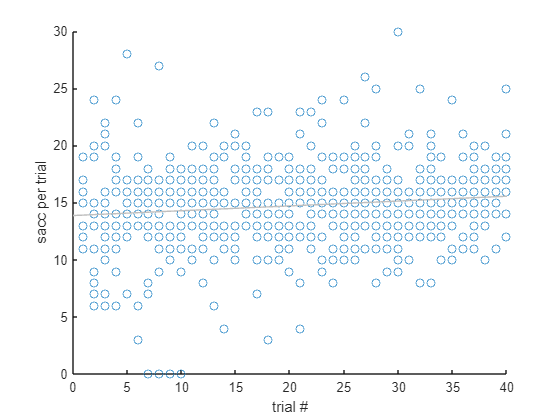

figure;scatter(trial_ind,sacc_trl_hist_mat); lsline; ylabel('sacc per trial');xlabel('trial #')

%looks like there is a positive correlation between the trial# and n of
%sacc/trial. i would take it with a grain of salt, since there are some
%trials with 0 saccades, need to check why and/or exclude those trials.


%excluding the trials with zero saccades
zero_ind = find(sacc_trl_hist_mat==0);

sacc_trl_hist_mat(zero_ind)=[];
subj_id(zero_ind) = [];
trial_ind(zero_ind) = [];

tbl = table(subj_id', trial_ind', sacc_trl_hist_mat','VariableNames',{'subj_id','trial_ind','sacc_trl'});

lme = fitlme(tbl,'sacc_trl ~ 1 + trial_ind + (1|subj_id)')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             716
    Fixed effects coefficients           2
    Random effects coefficients         18
    Covariance parameters                2

Formula:
    sacc_trl ~ 1 + trial_ind + (1 | subj_id)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    3430.2    3448.5    -1711.1          3422.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF     pValue         Lower       Upper   
    {'(Intercept)'}          14.088      0.52868    26.648    714    3.7769e-109       13.05      15.126
    {'trial_ind'  }        0.034981    0.0082017    4.2652    714     2.2665e-05    0.018879    0.051084

Random effects covariance parameters (95% CIs):
Group: subj_id (18 Levels)
    Name1                  Name2                  Type 

p_lme = lme.Coefficients(2,6);

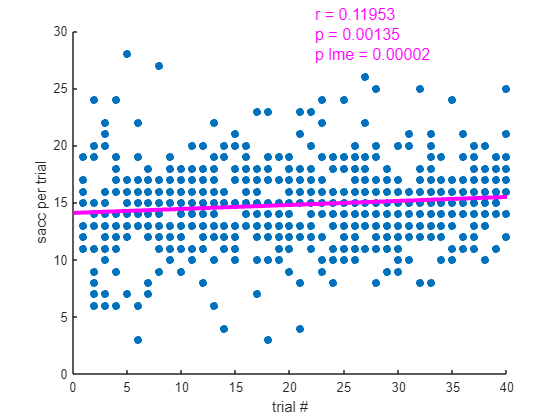

figure;scatter(trial_ind,sacc_trl_hist_mat,'o','filled'); lsline; ylabel('sacc per trial');xlabel('trial #');
h=lsline;
h.LineWidth = 3;
h.Color = 'm';

hold on; [r p] = corr(trial_ind',sacc_trl_hist_mat','Type','Spearman'); annotation('textbox',...
    [0.55 0.85 0.35 0.15],...
    'String',{sprintf('r = %0.5f \np = %0.5f \np lme = %0.5f', r, p, p_lme)},...
    'FontSize',12,...
    'FontName','Arial',...
    'LineStyle','--',...
    'EdgeColor',[1 1 1],...
    'LineWidth',2,...
    'BackgroundColor',[1 1 1],...
    'Color','m');

%there seems to be a week linear correlation, even when the zero sacc
%trials are excluded

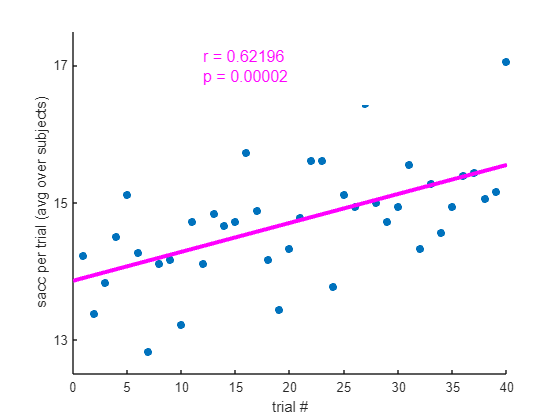

% sacc_trl_hist = sacc_trl_hist';
% sacc_trl_hist_avg = mean(cell2mat(sacc_trl_hist));

figure;scatter([1:numel(sacc_trl_hist_avg)], sacc_trl_hist_avg,'o','filled');
lsline
h=lsline;
h.LineWidth = 3;
h.Color = 'm';
xlabel('trial #'); ylabel('sacc per trial (avg over subjects)');yticks([13 15 17]);yticklabels({'13', '15', '17'})
[r p] = corr(sacc_trl_hist_avg',[1:numel(sacc_trl_hist_avg)]','Type','Spearman');
annotation('textbox',...
    [0.35 0.75 0.35 0.15],...
    'String',{sprintf('r = %0.5f \np = %0.5f', r, p)},...
    'FontSize',12,...
    'FontName','Arial',...
    'LineStyle','--',...
    'EdgeColor',[1 1 1],...
    'LineWidth',2,...
    'BackgroundColor',[1 1 1],...
    'Color','m');


filelist = ls;
load trial_limits_ind;

addpath C:\Users\ivans\Downloads\code\fastsmooth;

count_ch=1;


for i = 1:size(filelist,1)
    tic
    if contains(filelist(i,:), 'ds_ref')
        tic
        load(sprintf('%s',filelist(i,:)));
        Fs = freq; 
        nyq_freq = freq/2;
        HF_freq_low = 70 / nyq_freq;
        HF_freq_high = 200 / nyq_freq;
        [A,B] = cheby1(4, 0.1, [HF_freq_low, HF_freq_high]);


        trace_filt = filtfilt(A, B, ch_highpass_cleaned);
        HFA = abs(hilbert(trace_filt));%f
        Timestamps_eeg_ms = int64(Timestamps_ms);

        sacc_count = 1;
        for ii = 1:size(saccade,1)
            if strcmp(saccade.patient_id(ii),'TWH173')==1
                start_ts = int64(round(saccade.start_timestamp(ii)*1000));
                end_ts = int64(round(saccade.end_timestamp(ii)*1000));

                start_ts_ind_eeg = find(Timestamps_eeg_ms==start_ts);
                end_ts_ind_eeg = find(Timestamps_eeg_ms==end_ts);

                HFA_peri_sacc_start(sacc_count,:) = HFA((start_ts_ind_eeg - 200):(start_ts_ind_eeg+200));
                HFA_peri_sacc_end(sacc_count,:) = HFA((end_ts_ind_eeg - 200):(end_ts_ind_eeg+200)); sacc_count = sacc_count+1;
            end
        end
        HFA_all_sacc(count_ch).per_sacc_start = HFA_peri_sacc_start; clear HFA_peri_sacc_start;
         HFA_all_sacc(count_ch).per_sacc_end = HFA_peri_sacc_end; clear HFA_peri_sacc_end;
         HFA_all_sacc(count_ch).ch = sprintf('%s',filelist(i,:)); count_ch = count_ch + 1;
         toc
    end
end

Elapsed time is 4.800311 seconds.
Elapsed time is 5.262147 seconds.
Elapsed time is 4.788252 seconds.
Elapsed time is 4.741053 seconds.
Elapsed time is 4.839216 seconds.
Elapsed time is 4.543555 seconds.
Elapsed time is 4.526670 seconds.
Elapsed time is 4.663937 seconds.
Elapsed time is 4.992986 seconds.
Elapsed time is 5.734071 seconds.
Elapsed time is 4.765259 seconds.
Elapsed time is 4.840829 seconds.
Elapsed time is 4.936001 seconds.
Elapsed time is 4.807877 seconds.
Elapsed time is 5.193555 seconds.
Elapsed time is 4.747044 seconds.
Elapsed time is 4.568310 seconds.
Elapsed time is 4.723878 seconds.
Elapsed time is 5.403349 seconds.
Elapsed time is 4.934282 seconds.
Elapsed time is 6.389251 seconds.
Elapsed time is 4.639133 seconds.
Elapsed time is 4.720426 seconds.
Elapsed time is 4.591888 seconds.


      save('HFA_all_sacc','HFA_all_sacc'); clearvars -EXCEPT saccade;

for i = 1:numel(HFA_all_sacc)
    return_ind = find(HFA_all_sacc(i).saccade_return(:,3)==1);
    no_return_ind = find(HFA_all_sacc(i).saccade_return(:,3)==0);
    per_sac_start_return = mean(HFA_all_sacc(i).per_sacc_start(return_ind,:));
    per_sac_start_no_return = mean(HFA_all_sacc(i).per_sacc_start(no_return_ind,:));

    
    per_sacc_start_return_smooth = fastsmooth(per_sac_start_return,30,3,1);
    per_sacc_start_no_return_smooth = fastsmooth(per_sac_start_no_return,30,3,1);
    figure;hold on;plot(per_sacc_start_return_smooth(50:350));xline(150);
    plot(per_sacc_start_no_return_smooth(50:350),'r');xline(150);
end
